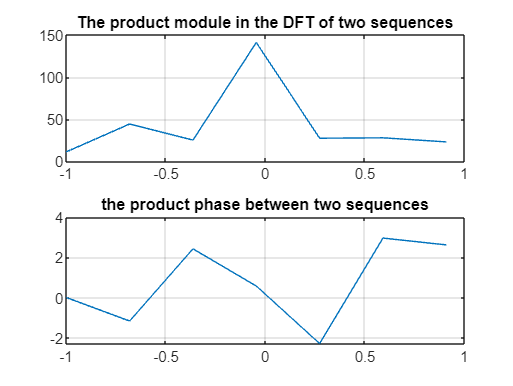

clear all
close all
w=-pi:pi;
x1=[3 4.2 11 0 7 -1 0 2];
x2=[1.2 3 0 -0.5 2];
y=conv(x1,x2);
X1=freqz(x1,1,w);
X2=freqz(x2,1,w);
X=X1.*X2;
Y=freqz(y,1,w);
subplot(211)
plot(w/pi,abs(X)); grid
title('The product module in the DFT of two sequences')
subplot(212)
plot(w/pi,angle(Y)); grid
title('the product phase between two sequences')